% %清空变量
% warning off
% close all
% clear,clc
% 设定当前图像的背景为白色
set(gcf, 'color', 'w');
% 获取当前图像对象中所有的子对象
allAxesInFigure = findall(gcf, 'type', 'axes');
% 将所有子对象的背景设为白色
set(allAxesInFigure,'color','w');

% msc
x_axis = linspace(42.21595, 3288.67847, 2048)% 拉曼峰移

x_axis = 	1.0e+03 *

    0.0422    0.0438    0.0454    0.0470    0.0486    0.0501    0.0517    0.0533    0.0549    0.0565    0.0581    0.0597    0.0612    0.0628    0.0644    0.0660    0.0676    0.0692    0.0708    0.0723    0.0739    0.0755    0.0771    0.0787    0.0803    0.0819    0.0835    0.0850    0.0866    0.0882    0.0898    0.0914    0.0930    0.0946    0.0961    0.0977    0.0993    0.1009    0.1025    0.1041    0.1057    0.1072    0.1088    0.1104    0.1120    0.1136    0.1152    0.1168    0.1183    0.1199


data_all=importdata('第一次实验的拉曼数据1.xls')

data_all = 包含以下字段的 struct :
    Sheet1: [2049×20 double]
    Sheet2: [2049×15 double]


data_all=data_all.Sheet1

data_all = 	1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0067    0.0075    0.0070    0.0039    0.0070    0.0059    0.0080    0.0054    0.0076    0.0062    0.0082    0.0076    0.0060    0.0045    0.0085    0.0054    0.0059    0.0046    0.0045    0.0043
    0.0073    0.0084    0.0083    0.0079    0.0073    0.0072    0.0081    0.0067    0.0063    0.0078    0.0081    0.0077    0.0077    0.0073    0.0082    0.0056    0.0066    0.0050    0.0043    0.0054
    0.0085    0.0099    0.0075    0.0075    0.0060    0.0064    0.0081    0.0085    0.0069    0.0063    0.0062    0.0091    0.0084    0.0078    0.0085    0.0047    0.0058    0.0066    0.0059    0.0066
    0.0093    0.0083    0.0078    0.0101    0.0065    0.0098    0.0085    0.0082    0.0087    0.0073    0.0079    0.0096    0.0088    0.0089    0.0101    0.0041    0.0047   

data_all=data_all'

data_all = 	1.0e+03 *

    0.0000    0.0067    0.0073    0.0085    0.0093    0.0088    0.0096    0.0085    0.0097    0.0116    0.0131    0.0121    0.0128    0.0147    0.0147    0.0170    0.0255    0.0363    0.0613    0.1172    0.2440    0.5361    1.0481    1.6861    2.2389    2.5964    2.7619    2.8322    2.8797    2.9565    2.9975    2.9416    2.9022    2.8879    2.9100    2.9172    2.9155    2.9259    2.9115    2.9069    2.9019    2.8919    2.8875    2.8938    2.9355    2.9192    2.9043    2.8960    2.9119    2.9125
    0.0000    0.0075    0.0084    0.0099    0.0083    0.0081    0.0099    0.0100    0.0121    0.0089    0.0129    0.0099    0.0136    0.0165    0.0163    0.0176    0.0246    0.0346    0.0601    0.1160    0.2488    0.5431    1.0504    1.6930    2.2433    2.6094    2.7715    2.8478    2.8997    2.9811    3.0151    2.9625    2.9169    2.9217    2.9229    2.9407    2.9320    2.9446    2.9296    2.9182    2.9295    2.9085    2.9008    2.8986    2.9436    2.9341    2.9344    2.

x=data_all(:,2:2049)

x = 	1.0e+03 *

    0.0067    0.0073    0.0085    0.0093    0.0088    0.0096    0.0085    0.0097    0.0116    0.0131    0.0121    0.0128    0.0147    0.0147    0.0170    0.0255    0.0363    0.0613    0.1172    0.2440    0.5361    1.0481    1.6861    2.2389    2.5964    2.7619    2.8322    2.8797    2.9565    2.9975    2.9416    2.9022    2.8879    2.9100    2.9172    2.9155    2.9259    2.9115    2.9069    2.9019    2.8919    2.8875    2.8938    2.9355    2.9192    2.9043    2.8960    2.9119    2.9125    2.9207
    0.0075    0.0084    0.0099    0.0083    0.0081    0.0099    0.0100    0.0121    0.0089    0.0129    0.0099    0.0136    0.0165    0.0163    0.0176    0.0246    0.0346    0.0601    0.1160    0.2488    0.5431    1.0504    1.6930    2.2433    2.6094    2.7715    2.8478    2.8997    2.9811    3.0151    2.9625    2.9169    2.9217    2.9229    2.9407    2.9320    2.9446    2.9296    2.9182    2.9295    2.9085    2.9008    2.8986    2.9436    2.9341    2.9344    2.9221    2.9300   

y=data_all(:,1)

y =     0.0065
    0.0065
    0.0065
    0.0065
    0.0065
    0.0100
    0.0100
    0.0100
    0.0100
    0.0100


V=ones(1,2048)

V =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


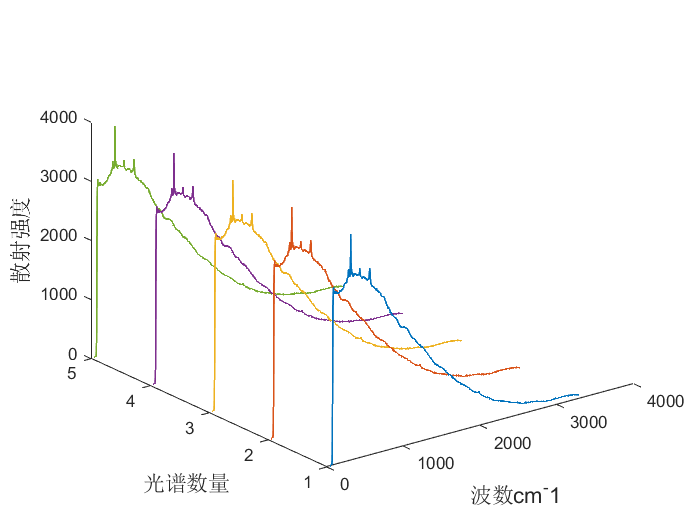

plot3(x_axis,V,data_all(1,2:2049),x_axis,2*V,data_all(1,2:2049), x_axis,3*V,data_all(1,2:2049),x_axis,4*V,data_all(1,2:2049),x_axis,5*V,data_all(1,2:2049),'linewidth',1.1)
xlabel('波数cm^-1','fontsize',13)
zlabel('散射强度','fontsize',13)
ylabel('光谱数量','fontsize',13)

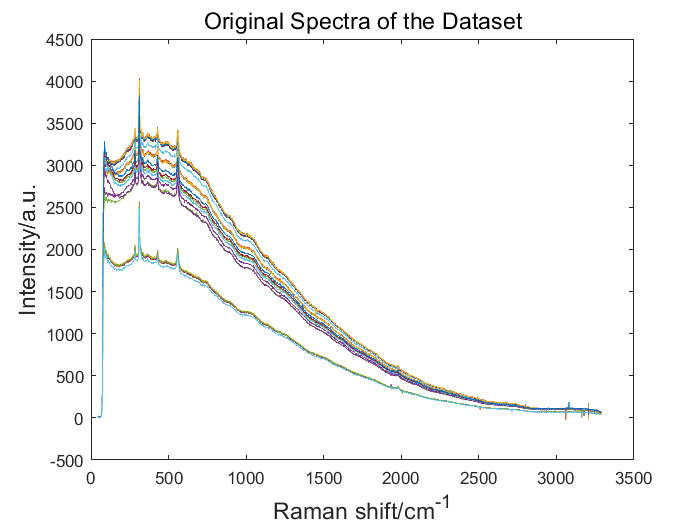

plot(x_axis,data_all(1:20,2:2049));
title("Original Spectra of the Dataset",'fontsize',14)
xlabel('Raman shift/cm^{-1}','fontsize',14)
ylabel('Intensity/a.u.','fontsize',14)


[x_svn] = snv(x)

x_svn =    -1.1224   -1.1218   -1.1208   -1.1201   -1.1205   -1.1198   -1.1208   -1.1196   -1.1179   -1.1165   -1.1175   -1.1168   -1.1151   -1.1151   -1.1130   -1.1053   -1.0954   -1.0725   -1.0215   -0.9058   -0.6390   -0.1714    0.4112    0.9160    1.2425    1.3936    1.4577    1.5012    1.5713    1.6087    1.5577    1.5217    1.5086    1.5288    1.5353    1.5338    1.5433    1.5302    1.5260    1.5214    1.5123    1.5082    1.5140    1.5521    1.5372    1.5236    1.5160    1.5305    1.5311    1.5385
   -1.1218   -1.1209   -1.1196   -1.1211   -1.1213   -1.1196   -1.1195   -1.1177   -1.1205   -1.1169   -1.1196   -1.1163   -1.1136   -1.1138   -1.1127   -1.1063   -1.0972   -1.0740   -1.0233   -0.9027   -0.6354   -0.1748    0.4087    0.9084    1.2409    1.3881    1.4573    1.5045    1.5784    1.6093    1.5615    1.5201    1.5245    1.5256    1.5418    1.5338    1.5452    1.5317    1.5213    1.5316    1.5125    1.5055    1.5035    1.5444    1.5357    1.5360    1.5249    1.5320    1.5339 

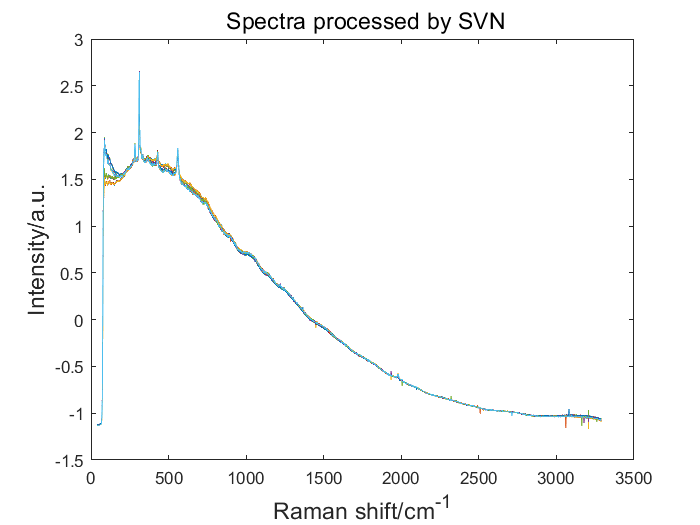

plot(x_axis,x_svn)
title(" Spectra processed by SVN",'fontsize',14)
xlabel('Raman shift/cm^{-1}','fontsize',14)
ylabel('Intensity/a.u.','fontsize',14)

%  airpls 基线校正
[x_baseline,Z1]=airPLS(x_svn,10e5,2,0.1,0.5,20)

x_baseline =    -0.1271   -0.1639   -0.2003   -0.2370   -0.2748   -0.3115   -0.3500   -0.3862   -0.4219   -0.4579   -0.4962   -0.5329   -0.5685   -0.6058   -0.6410   -0.6705   -0.6978   -0.7120   -0.6980   -0.6191   -0.3892    0.0417    0.5878    1.0562    1.3466    1.4617    1.4901    1.4980    1.5328    1.5353    1.4496    1.3791    1.3319    1.3183    1.2914    1.2568    1.2335    1.1879    1.1517    1.1154    1.0750    1.0400    1.0153    1.0233    0.9787    0.9358    0.8993    0.8853    0.8579    0.8377
   -0.1279   -0.1644   -0.2005   -0.2393   -0.2769   -0.3126   -0.3500   -0.3855   -0.4257   -0.4595   -0.4995   -0.5335   -0.5682   -0.6056   -0.6417   -0.6725   -0.7005   -0.7145   -0.7007   -0.6170   -0.3865    0.0375    0.5844    1.0479    1.3441    1.4554    1.4889    1.5006    1.5393    1.5352    1.4527    1.3770    1.3472    1.3146    1.2973    1.2562    1.2349    1.1890    1.1466    1.1252    1.0748    1.0370    1.0045    1.0153    0.9769    0.9480    0.9079    0.8866    0.

Z1 =    -0.9953   -0.9579   -0.9205   -0.8831   -0.8457   -0.8082   -0.7708   -0.7334   -0.6960   -0.6586   -0.6213   -0.5839   -0.5466   -0.5093   -0.4720   -0.4348   -0.3976   -0.3605   -0.3235   -0.2866   -0.2498   -0.2131   -0.1766   -0.1403   -0.1041   -0.0681   -0.0324    0.0031    0.0384    0.0734    0.1081    0.1425    0.1766    0.2104    0.2439    0.2770    0.3098    0.3422    0.3743    0.4060    0.4373    0.4682    0.4987    0.5288    0.5585    0.5878    0.6167    0.6452    0.6732    0.7008
   -0.9939   -0.9565   -0.9191   -0.8817   -0.8443   -0.8069   -0.7696   -0.7322   -0.6948   -0.6574   -0.6201   -0.5828   -0.5455   -0.5082   -0.4709   -0.4337   -0.3966   -0.3595   -0.3226   -0.2857   -0.2489   -0.2122   -0.1757   -0.1394   -0.1033   -0.0673   -0.0316    0.0039    0.0391    0.0741    0.1088    0.1432    0.1772    0.2110    0.2445    0.2776    0.3103    0.3427    0.3747    0.4064    0.4377    0.4685    0.4990    0.5291    0.5588    0.5881    0.6169    0.6453    0.6734    

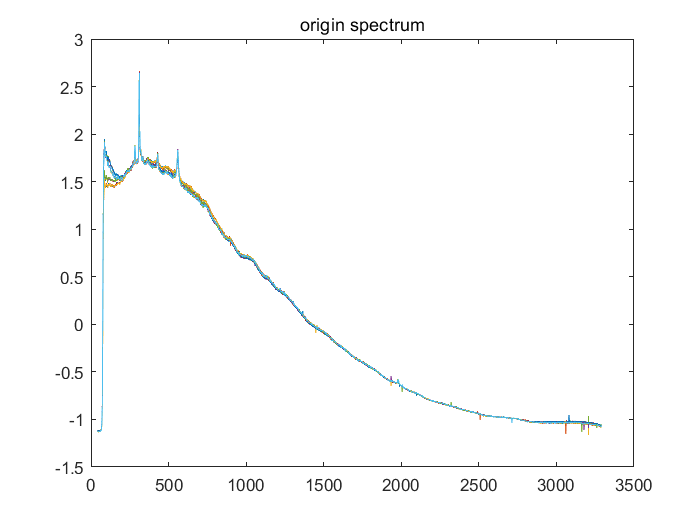

 plot(x_axis,x_svn)
 title('origin spectrum')

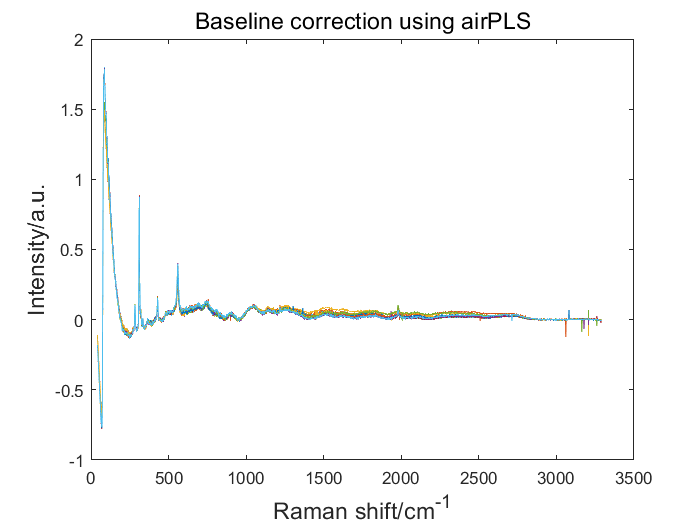

 plot(x_axis,x_baseline)
 title('Baseline correction using airPLS','fontsize',14)
 xlabel('Raman shift/cm^{-1}','fontsize',14)
 ylabel('Intensity/a.u.','fontsize',14)

% Savitzky-Golay滤波
x_sg = sgolayfilt(x_baseline',5,51)

x_sg =    -0.0764   -0.0775   -0.0769   -0.0792   -0.0783   -0.0669   -0.0652   -0.0662   -0.0666   -0.0657   -0.1251   -0.1265   -0.1263   -0.1301   -0.1258   -0.1255   -0.1235   -0.1263   -0.1253   -0.1241
   -0.0927   -0.0937   -0.0921   -0.0950   -0.0956   -0.0831   -0.0818   -0.0842   -0.0820   -0.0822   -0.1436   -0.1440   -0.1431   -0.1451   -0.1426   -0.1428   -0.1416   -0.1427   -0.1426   -0.1418
   -0.1385   -0.1393   -0.1370   -0.1404   -0.1421   -0.1280   -0.1268   -0.1303   -0.1263   -0.1273   -0.1942   -0.1939   -0.1925   -0.1932   -0.1919   -0.1923   -0.1916   -0.1915   -0.1919   -0.1914
   -0.2043   -0.2050   -0.2022   -0.2059   -0.2083   -0.1922   -0.1912   -0.1951   -0.1901   -0.1916   -0.2662   -0.2655   -0.2638   -0.2637   -0.2631   -0.2633   -0.2630   -0.2621   -0.2627   -0.2625
   -0.2816   -0.2823   -0.2793   -0.2831   -0.2860   -0.2678   -0.2668   -0.2708   -0.2654   -0.2672   -0.3504   -0.3496   -0.3477   -0.3470   -0.3468   -0.3466   -0.3466   -0.3452   -0.345

x_sg = x_sg'

x_sg =    -0.0764   -0.0927   -0.1385   -0.2043   -0.2816   -0.3632   -0.4429   -0.5155   -0.5768   -0.6234   -0.6527   -0.6628   -0.6528   -0.6222   -0.5712   -0.5004   -0.4111   -0.3050   -0.1839   -0.0503    0.0933    0.2442    0.3992    0.5555    0.7100    0.8596    0.9829    1.0951    1.1955    1.2822    1.3535    1.4083    1.4457    1.4651    1.4665    1.4508    1.4189    1.3718    1.3127    1.2442    1.1701    1.0942    1.0218    0.9578    0.9078    0.8741    0.8557    0.8449    0.8322    0.8145
   -0.0775   -0.0937   -0.1393   -0.2050   -0.2823   -0.3640   -0.4439   -0.5167   -0.5781   -0.6248   -0.6542   -0.6645   -0.6546   -0.6241   -0.5731   -0.5024   -0.4130   -0.3068   -0.1857   -0.0519    0.0919    0.2428    0.3981    0.5546    0.7093    0.8591    0.9827    1.0956    1.1960    1.2826    1.3538    1.4085    1.4461    1.4658    1.4677    1.4520    1.4200    1.3731    1.3136    1.2452    1.1714    1.0959    1.0234    0.9593    0.9089    0.8749    0.8562    0.8452    0.8326  

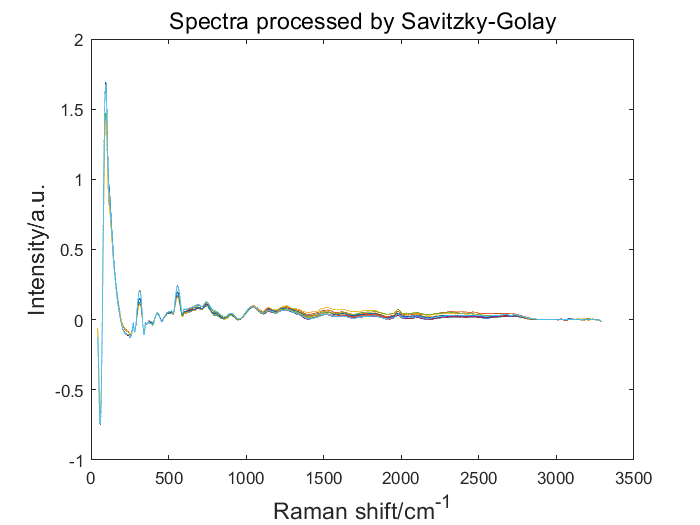

plot(x_axis,x_sg)
title('Spectra processed by Savitzky-Golay','fontsize',14)
xlabel('Raman shift/cm^{-1}','fontsize',14)
ylabel('Intensity/a.u.','fontsize',14)

%主成分分析
[coeff,score,latent,tsquared,explained] = pca(x_sg);


%主成分分布
% explained %贡献率
% scatter3(score(:,1),score(:,2),score(:,3),'kp','filled')
% axis equal
% title('主成分分布图')
% xlabel('1st Principal Component')
% ylabel('2nd Principal Component')
% zlabel('3rd Principal Component')

explained %贡献率

explained =    77.0394
   14.8926
    6.2116
    0.7415
    0.4357
    0.2847
    0.0811
    0.0514
    0.0404
    0.0371


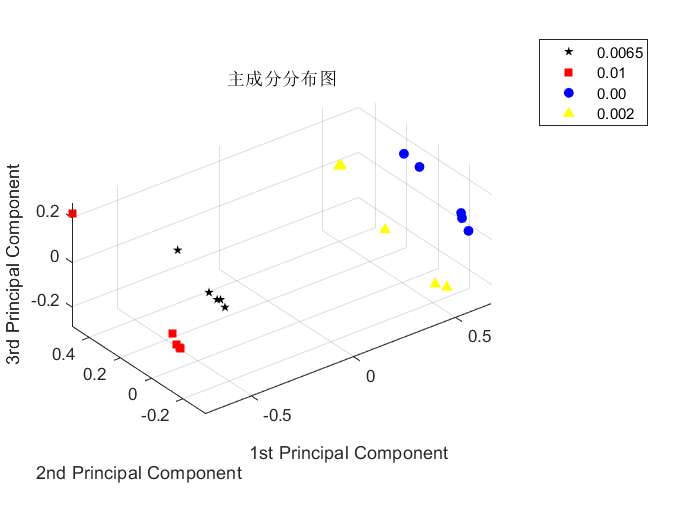

scatter3(score(1:5,1),score(1:5,2),score(1:5,3),'kp','filled')
hold on

scatter3(score(6:10,1),score(6:10,2),score(6:10,3),'rs','filled')
hold on

scatter3(score(11:15,1),score(11:15,2),score(11:15,3),'bo','filled')
hold on

scatter3(score(16:20,1),score(16:20,2),score(16:20,3),'y^','filled')
hold off

legend('0.0065','0.01','0.00','0.002')

axis equal
title('主成分分布图')
xlabel('1st Principal Component')
ylabel('2nd Principal Component')
zlabel('3rd Principal Component')

% % pc1强度
% coeff_T = coeff'
% % 拉曼峰移
% % plot(x_axis,coeff_T(15,:),'k',x_axis,coeff_T(1,:),'b')
% plot(x_axis,coeff_T(1,:),'k',x_axis,coeff_T(14,:),'b')
% title('PC1主成分系数')
% xlabel('拉曼散射（cm^-1）')
% ylabel('PC1载荷强度')


[coeff_00065] = pca(x_sg(1:5,1:2048));
% [coeff_00065,Z1]=airPLS(coeff_00065,10e5,2,0.1,0.5,20)

[coeff_001] = pca(x_sg(6:10,1:2048));
% [coeff_001,Z2]=airPLS(coeff_001,10e5,2,0.1,0.5,20)

[coeff_00] = pca(x_sg(11:15,1:2048));
% [coeff_001,Z3]=airPLS(coeff_001,10e5,2,0.1,0.5,20)


[coeff_0002] = pca(x_sg(16:20,1:2048));
% [coeff_0002,Z4]=airPLS(coeff_0002,10e5,2,0.1,0.5,20)

% pc1强度
coeff_T_00065 = coeff_00065'

coeff_T_00065 =     0.0022    0.0029    0.0034    0.0036    0.0037    0.0036    0.0034    0.0030    0.0024    0.0018    0.0010    0.0002   -0.0008   -0.0017   -0.0028   -0.0038   -0.0048   -0.0059   -0.0069   -0.0079   -0.0088   -0.0097   -0.0104   -0.0111   -0.0117   -0.0122   -0.0125   -0.0119   -0.0128   -0.0132   -0.0131   -0.0132   -0.0126   -0.0119   -0.0100   -0.0086   -0.0074   -0.0059   -0.0055   -0.0031   -0.0008    0.0011    0.0011    0.0018    0.0009    0.0018    0.0021    0.0036    0.0052    0.0060
   -0.0240   -0.0151   -0.0092   -0.0059   -0.0044   -0.0044   -0.0054   -0.0071   -0.0091   -0.0111   -0.0130   -0.0146   -0.0156   -0.0160   -0.0157   -0.0147   -0.0130   -0.0105   -0.0073   -0.0035    0.0008    0.0056    0.0108    0.0161    0.0216    0.0271    0.0334    0.0429    0.0466    0.0440    0.0424    0.0428    0.0456    0.0471    0.0447    0.0414    0.0370    0.0342    0.0300    0.0245    0.0229    0.0210    0.0216    0.0191    0.0171    0.0112    0.0065   -0.0014   


coeff_T_001 = coeff_001'

coeff_T_001 =     0.0006    0.0007    0.0007    0.0007    0.0006    0.0005    0.0004    0.0003    0.0003    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0007    0.0009    0.0011    0.0012    0.0014    0.0016    0.0017    0.0017    0.0018    0.0016    0.0014    0.0016    0.0017    0.0020    0.0019    0.0019    0.0023    0.0029    0.0031    0.0027    0.0024    0.0019    0.0012    0.0009    0.0005   -0.0000   -0.0002   -0.0006   -0.0005   -0.0004   -0.0011
   -0.0133    0.0146    0.0330    0.0433    0.0471    0.0456    0.0402    0.0318    0.0214    0.0099   -0.0020   -0.0137   -0.0247   -0.0345   -0.0428   -0.0493   -0.0538   -0.0563   -0.0566   -0.0548   -0.0509   -0.0451   -0.0375   -0.0283   -0.0178   -0.0061    0.0066    0.0205    0.0313    0.0391    0.0527    0.0632    0.0749    0.0857    0.0938    0.1001    0.1035    0.1080    0.1084    0.1047    0.1016    0.0909    0.0806    0.0716    0.0525    0.0387    0.0353    0.0298    0


coeff_T_00 = coeff_00'

coeff_T_00 =     0.0069    0.0036    0.0013   -0.0000   -0.0007   -0.0008   -0.0006   -0.0001    0.0006    0.0013    0.0021    0.0027    0.0033    0.0037    0.0039    0.0039    0.0038    0.0034    0.0029    0.0022    0.0014    0.0005   -0.0005   -0.0015   -0.0026   -0.0036   -0.0038   -0.0044   -0.0049   -0.0051   -0.0049   -0.0047   -0.0048   -0.0049   -0.0043   -0.0039   -0.0030   -0.0029   -0.0018   -0.0020   -0.0012   -0.0006   -0.0008   -0.0011   -0.0011   -0.0013   -0.0012   -0.0012   -0.0025   -0.0028
    0.0334    0.0070   -0.0120   -0.0246   -0.0319   -0.0348   -0.0341   -0.0306   -0.0251   -0.0181   -0.0101   -0.0017    0.0069    0.0152    0.0229    0.0299    0.0360    0.0410    0.0450    0.0477    0.0493    0.0498    0.0493    0.0477    0.0453    0.0422    0.0399    0.0362    0.0333    0.0272    0.0253    0.0233    0.0213    0.0182    0.0167    0.0144    0.0149    0.0104    0.0080    0.0095    0.0142    0.0153    0.0166    0.0208    0.0282    0.0334    0.0392    0.0434    0.


coeff_T_00002 = coeff_0002'

coeff_T_00002 =     0.0011    0.0000   -0.0006   -0.0010   -0.0012   -0.0011   -0.0010   -0.0007   -0.0005   -0.0002    0.0001    0.0004    0.0006    0.0008    0.0009    0.0009    0.0009    0.0009    0.0008    0.0006    0.0005    0.0003    0.0001   -0.0001   -0.0002   -0.0003   -0.0004   -0.0001    0.0006    0.0011    0.0018    0.0029    0.0036    0.0043    0.0042    0.0042    0.0044    0.0042    0.0039    0.0030    0.0028    0.0022    0.0021    0.0013    0.0011    0.0009    0.0001   -0.0005   -0.0010   -0.0008
   -0.0015   -0.0016   -0.0017   -0.0018   -0.0019   -0.0019   -0.0019   -0.0018   -0.0017   -0.0015   -0.0013   -0.0010   -0.0006   -0.0002    0.0002    0.0008    0.0013    0.0019    0.0026    0.0032    0.0039    0.0046    0.0053    0.0060    0.0067    0.0074    0.0078    0.0084    0.0096    0.0111    0.0118    0.0123    0.0115    0.0100    0.0097    0.0091    0.0080    0.0080    0.0059    0.0055    0.0059    0.0046    0.0035    0.0024    0.0017    0.0014    0.0008    0.0021   


% % 合并pc1系数矩阵
% matrix_pc1(1,:) = coeff_T_00065(1,:)
% matrix_pc1(2,:) = coeff_T_001(1,:)
% matrix_pc1(3,:) = coeff_T_00(1,:)
% matrix_pc1(4,:) = coeff_T_00002(1,:)
% 
% [matrix_pc1] = MCS(matrix_pc1)
% 
% [matrix_pc1,Z]=airPLS(matrix_pc1,10e5,2,0.1,0.5,20)
% 
% matrix_pc1 = sgolayfilt(matrix_pc1',11,51)
% matrix_pc1 = matrix_pc1'
% 
% coeff_T_00065(1,:) = matrix_pc1(1,:)
% coeff_T_001(1,:) =  matrix_pc1(2,:)
% coeff_T_00(1,:) = matrix_pc1(3,:)
% coeff_T_00002(1,:) = matrix_pc1(4,:)


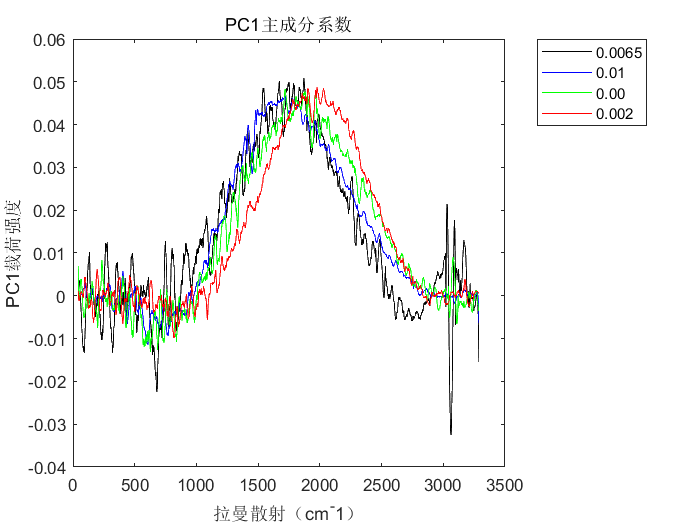


% 拉曼峰移
% plot(x_axis,coeff(15,:),'k',x_axis,coeff_T(1,:),'b')
plot(x_axis,coeff_T_00065(1,:),'k',x_axis,coeff_T_001(1,:),'b',x_axis,coeff_T_00(1,:),'g',x_axis,coeff_T_00002(1,:),'r')

legend('0.0065','0.01','0.00','0.002')

title('PC1主成分系数')
xlabel('拉曼散射（cm^-1）')
ylabel('PC1载荷强度')